
% Generate random signal, 
AL_ref = [2,0,2,0,0,9,3,3,4]; % Andrew's student number
FC_ref = [2,0,2,0,3,2,1,1,7]; % Frank's student number
x1 = repmat(AL_ref,1,100) 

x1 =      2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0


x1 = x1 - repmat(mean(x1),1,900)

x1 =    -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556


x2 = repmat(FC_ref,1,100) 

x2 =      2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3


x2 = x2 - repmat(mean(x2),1,900)

x2 =      0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1


fs = round((9334+2117)/2)

fs = 5726

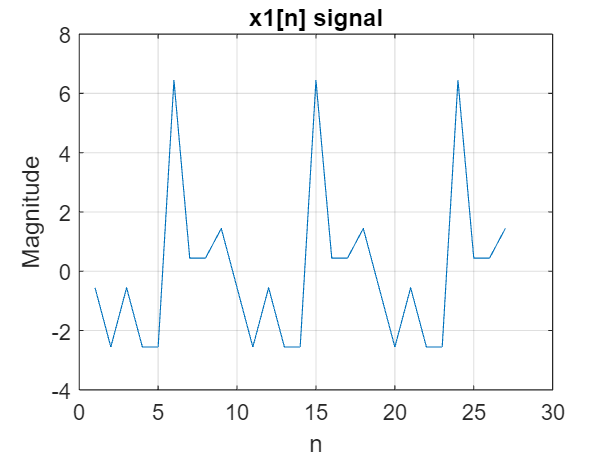



% Plot time signals
figure;
plot(1:27,x1(1:27));
title('x1[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

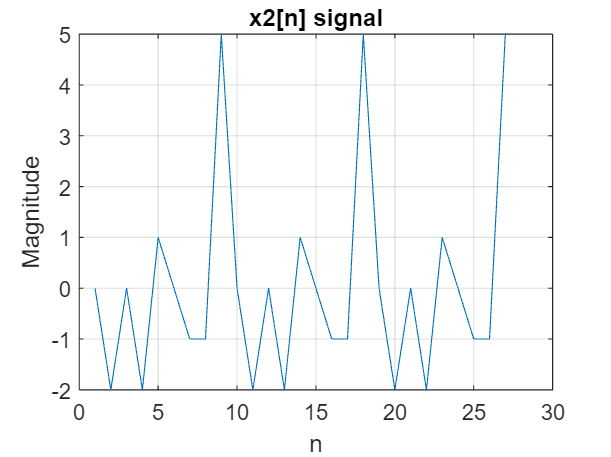

figure;
plot(1:27,x2(1:27));
title('x2[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

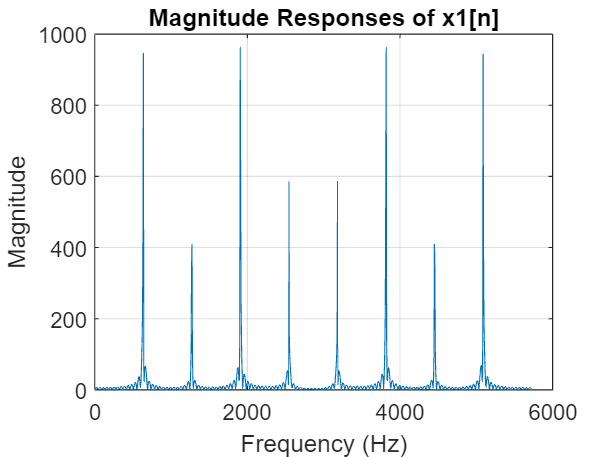


% Find magnitude reponse
N_FFT = 1024; % FFT size
X1 = fft(x1,N_FFT);
X2 = fft(x2,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis,abs(X1));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

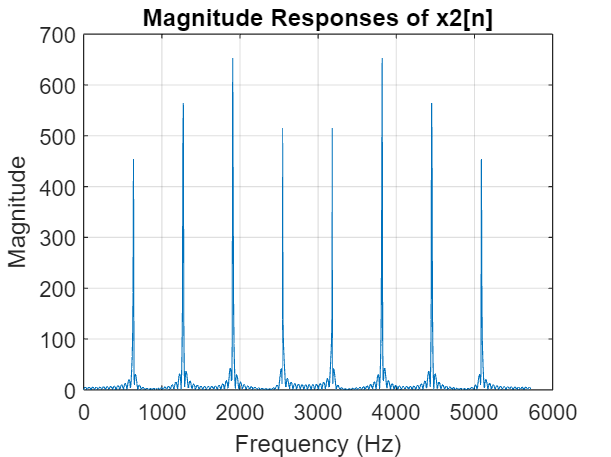

figure;
plot(f_axis,abs(X2));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

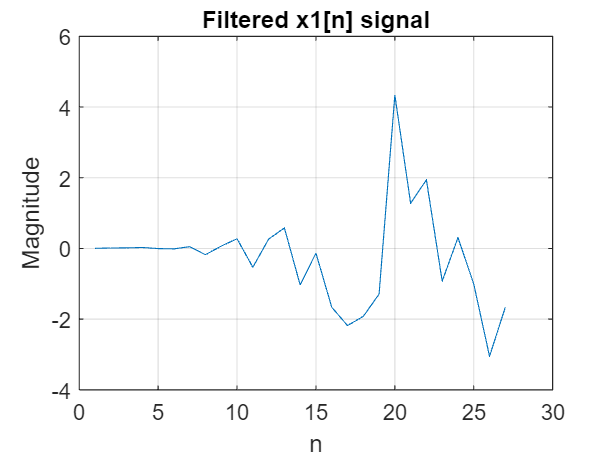

filt_x1 = filter(Num1, 1,x1);
filt_x2 = filter(Num2, 1,x2);

% Plot time signals
figure;
plot(1:27,filt_x1(1:27));
title('Filtered x1[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

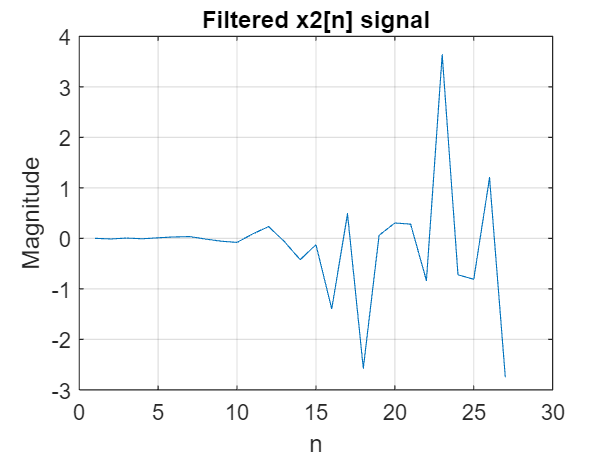

figure;
plot(1:27,filt_x2(1:27));
title('Filtered x2[n] signal')
xlabel('n');
ylabel('Magnitude');
grid on;

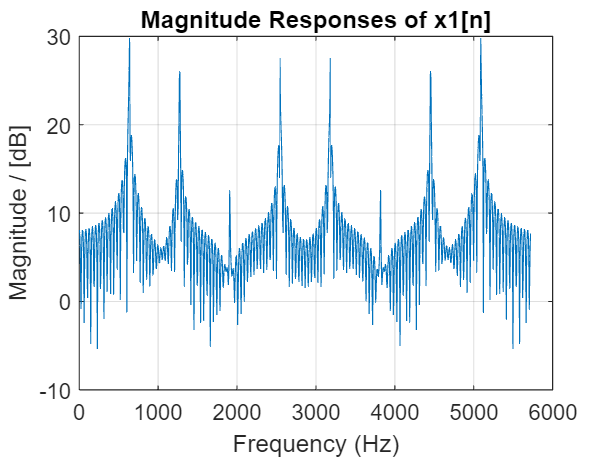


% Find magnitude reponse
N_FFT = 1024; % FFT size
X1 = fft(filt_x1,N_FFT);
X2 = fft(filt_x2,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis,10*log10(abs(X1)));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude / [dB]');
grid on;

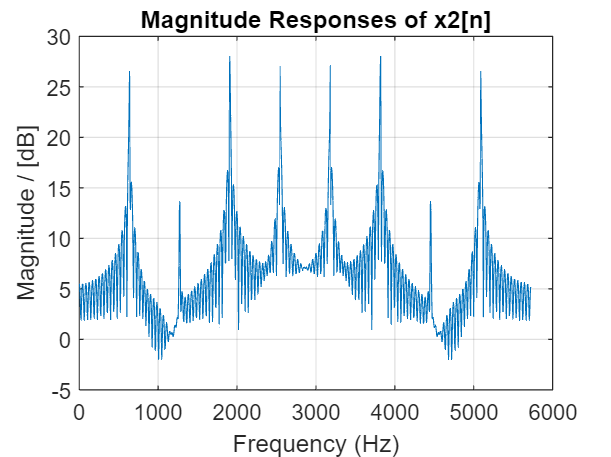

figure;
plot(f_axis,10*log10(abs(X2)));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude / [dB]');
grid on;

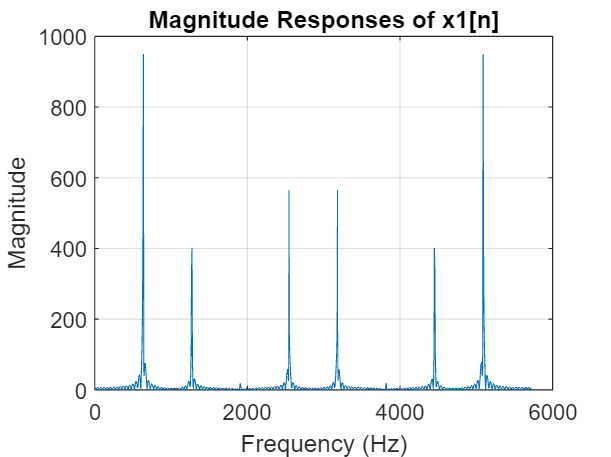

figure;
plot(f_axis,abs(X1));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

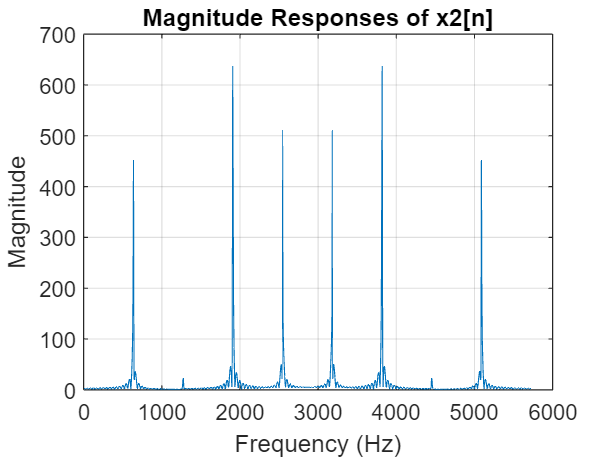

figure;
plot(f_axis,abs(X2));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

filter_a = single(Num1);
filter_b = single(Num2); 

save("AssData.mat")


FC_filtered = conv(filter_b,x2,"full")'
AL_filtered = conv(filter_a,x1,"full")'

AL_ccs = readmatrix('C:\Users\frank\OneDrive\Strathclyde\Strathclyde\Year5\EE580\S2\Assignment\Assigment_1_FIR\Debug\filter_AL.txt')
FC_ccs = readmatrix('C:\Users\frank\OneDrive\Strathclyde\Strathclyde\Year5\EE580\S2\Assignment\Assigment_1_FIR\Debug\filter_FC.txt')

diff_FCdB = 10*log10(sum((FC_ccs-FC_filtered).^2))

diff_FCdB = single
-98.4886

diff_ALdB = 10*log10(sum((AL_ccs-AL_filtered).^2))

diff_ALdB = single
-95.6367


diff_FC =(sum((FC_ccs-FC_filtered).^2))

diff_FC = single
1.4163e-10

diff_AL =(sum((AL_ccs-AL_filtered).^2))

diff_AL = single
2.7311e-10

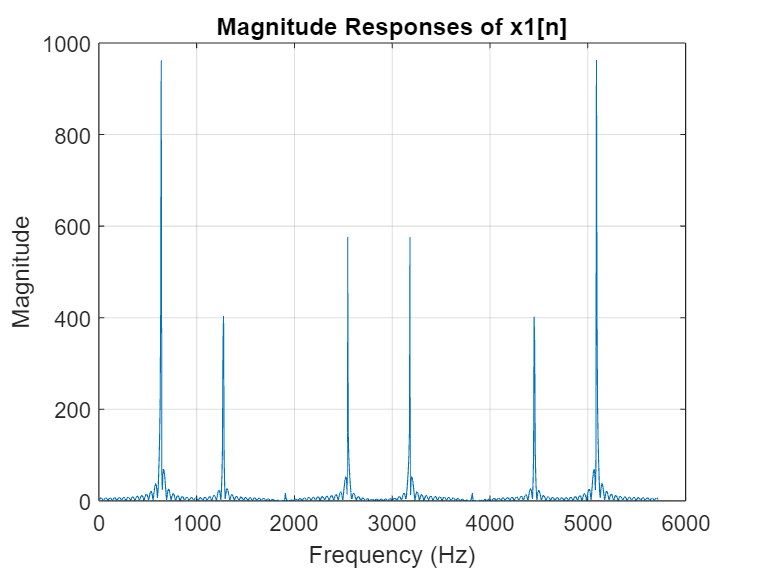

% Find magnitude reponse
N_FFT = 1024; % FFT size
Filtered_X1 = fft(AL_ccs,N_FFT);
Filtered_X2 = fft(FC_ccs,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis,abs(Filtered_X1));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

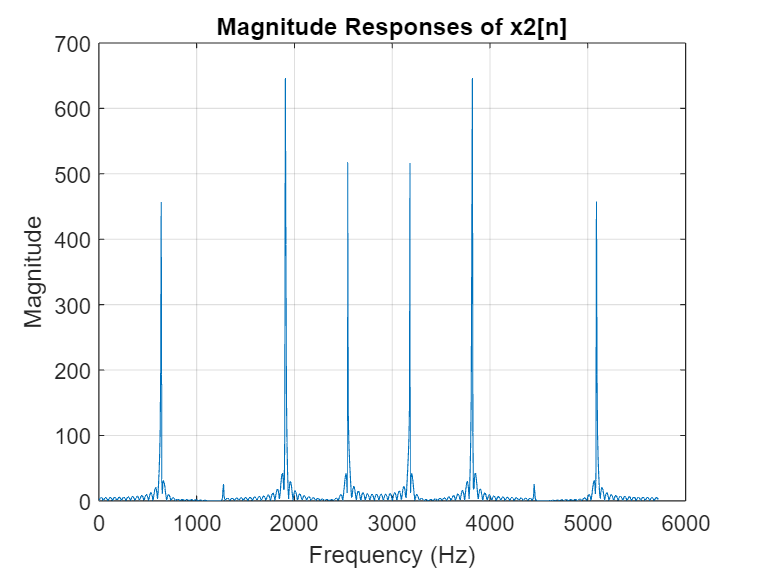

figure;
plot(f_axis,abs(Filtered_X2));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;